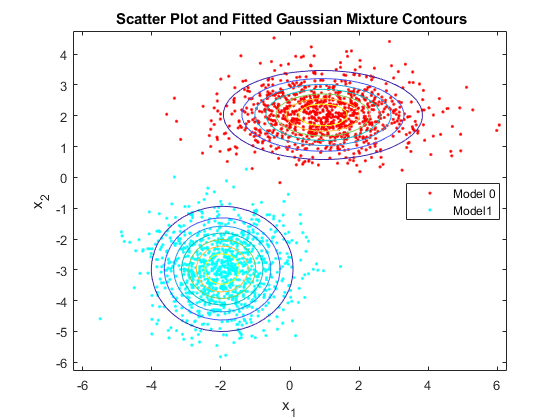

close all;clear all;clc
mu1 = [1 2];
Sigma1 = [2 0; 0 0.5];
mu2 = [-2 -3];
Sigma2 = [1 0;0 1];
rng('default'); % For reproducibility
X = [mvnrnd(mu1,Sigma1,1000);mvnrnd(mu2,Sigma2,1000)];
[mu,var]=fitgmm(X,2);
%GMModel = fitgmdist(X,2);
figure
y = [zeros(1000,1);ones(1000,1)];
h = gscatter(X(:,1),X(:,2),y);
hold on
gm = gmdistribution(mu,var);
ezcontour(@(x1,x2)pdf(gm,[x1 x2]),get(gca,{'XLim','YLim'}))
title('{\bf Scatter Plot and Fitted Gaussian Mixture Contours}')
legend(h,'Model 0','Model1')
hold off

function [mu,var]=fitgmm(x,n)
    m = size(x,2);
    mu = zeros(n,m);% mean
    var = zeros(m,m,n);
    
    id = randperm(size(x,1),n);
    mu = x(id,:);
    p0 = 1/n.*ones(1,n);
    sigma0 = 1;
    for i = 1:n
        var(:,:,i) = eye(m).*sigma0;
    end
    maxiter = 1000;
    for iter=1:maxiter
        % compute posterior probability
        pp = zeros(size(x,1),n);
        for j = 1:n
            err = x-repmat(mu(j,:),size(x,1),1);
            pp(:,j) = 1/sqrt((2*pi)^m*det(var(:,:,j))).*exp(-0.5.*diag((err)*inv(var(:,:,j))*err')).*p0(j);
        end
        % normalization
        den = sum(pp,2);
        pp = pp ./ den;
        
        % update mu and var
        for j=1:n
            mu(j,:) = sum(pp(:,j).*x)./(sum(pp(:,j)));
            err = x-repmat(mu(j,:),size(x,1),1);
            err = sqrt(pp(:,j)).*err;
            var(:,:,j)=(err'*err)./(sum(pp(:,j)));
        end
        
        % update prior
        oldp0 = p0;
        p0 = sum(pp)./size(x,1);
        
        if norm(oldp0-p0) < 1e-6
            break;
        end
    end
end